## plot one channel's spectrum

chann_num = 1

chann_num = 1

sample_from_batch_num = 1

sample_from_batch_num = 1

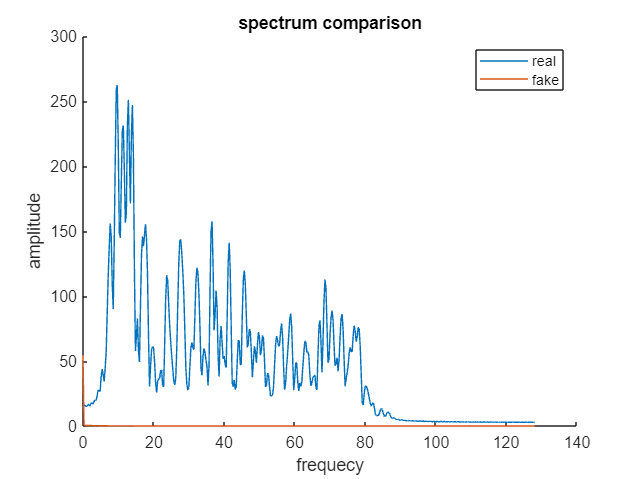

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
% spectrum_real = spectral_real(sample_from_batch_num, chann_num, :);
% spectrum_fake = spectral_fake(sample_from_batch_num, chann_num, :);
spectrum_real = spectral_real(:, chann_num, :);
spectrum_fake = spectral_fake(:, chann_num, :);
spectrum_real = mean(spectrum_real, 1);
spectrum_fake = mean(spectrum_fake, 1);
spectrum_real = spectrum_real(:);
spectrum_fake = spectrum_fake(:);
hold on 
plot(freqs, spectrum_real, 'DisplayName', 'real')
plot(freqs, spectrum_fake, 'DisplayName', 'fake')
hold off

title('spectrum comparison')
xlabel('frequecy')
ylabel('amplitude')
legend

## plot all channels spectrum

sample_from_batch_num = 1;

% Define the condition for averaging (replace with your specific condition)
average_condition = true;  % Example condition, replace with your logic

if average_condition
  % Calculate average spectrum across channels
  spectrum_real = mean(squeeze(spectral_real(sample_from_batch_num, :, :)), 1);
  spectrum_fake = mean(squeeze(spectral_fake(sample_from_batch_num, :, :)), 1);
else
  spectrum_real = squeeze(spectral_real(sample_from_batch_num, :, :)); 
  spectrum_fake = squeeze(spectral_fake(sample_from_batch_num, :, :));
end

% Plotting
hold_on = true;  % Adjust based on your preference

figure;  % Create a new figure window

if hold_on
  hold on;  % Enable hold for plotting on the same figure
end

plot(freqs, spectrum_real, 'DisplayName', 'Real (Avg)');
plot(freqs, spectrum_fake, 'DisplayName', 'Fake (Avg)');

if hold_on
  hold off;  % Disable hold if using hold_on
end

title('Spectrum Comparison (Conditional Average)');
xlabel('Frequency');
ylabel('Amplitude');
legend;


## plot one channel's raw samples

chann_num = 1
sample_from_batch_num = 1
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
signal_real = squeeze(X_real(sample_from_batch_num, chann_num, :));
signal_fake = squeeze(X_fake(sample_from_batch_num, chann_num, :));
hold on 
plot(signal_real, 'DisplayName', 'real')
plot(signal_fake, 'DisplayName', 'fake')
hold off

title('time series comparison')
xlabel('sample')
ylabel('amplitude')
legend

## plot all channels raw samples

sample_from_batch_num = 1
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
clf
signal_real = squeeze(X_real(sample_from_batch_num, :, :))';
signal_fake = squeeze(X_fake(sample_from_batch_num, :, :))';
hold on 
plot(signal_real, 'DisplayName', 'real')
plot(signal_fake, 'DisplayName', 'fake')
hold off

title('time series comparison')
xlabel('sample')
ylabel('amplitude')
legend

## plot one channel's spectrum calculated from raw signals

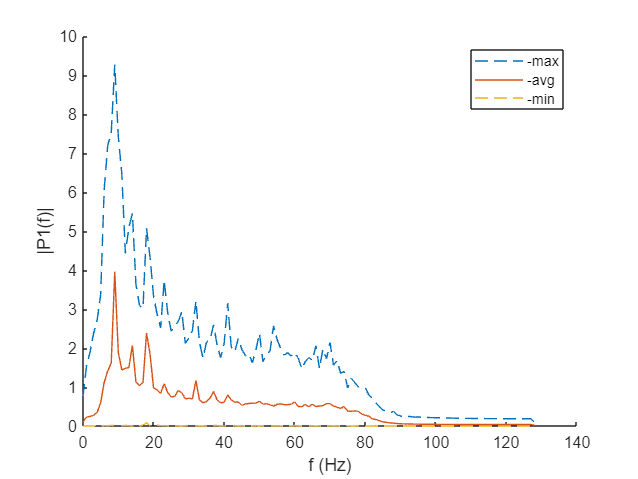

clf
% plot_fft_stats(X_real)

X=X_real(:,:,1:256); % remove laset zero values
X = permute(X, [3 1 2]);
% if nargin == 1
name = '';
% end
Fs = 256;
L = 256;
% BS=buffer(X,256,0);
P1_all = zeros([size(BS, 2), 129]);
BS = X;
for i = 1:size(BS, 2)
    f = Fs*(0:(L/2))/L;
    Y = fft(BS(:, i)');
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    P1_all(i, :) = P1;
end
P1_means = mean(P1_all, 1);
P1_max = max(P1_all, [], 1);
P1_min = min(P1_all, [], 1);
hold on
plot(f, P1_max,'--', 'DisplayName', strcat([name, '-max']));
plot(f, P1_means, 'DisplayName', strcat([name, '-avg']));
plot(f, P1_min,'--', 'DisplayName', strcat([name, '-min']));
% plot(f,P1_means+std(P1_all, [], 1),'--');
% plot(f,P1_means-std(P1_all, [], 1),'--');
legend
hold off
xlabel("f (Hz)")
ylabel("|P1(f)|")

## functions

function plot_fft_stats_already_buffered(X, name)
if nargin == 1
    name = '';
end
Fs = 256;
L = 256;
% BS=buffer(X,256,0);
% P1_all = zeros([size(BS, 2), 129]);
BS = X;
for i = 1:size(BS, 2)
    f = Fs*(0:(L/2))/L;
    Y = fft(BS(:, i)');
    P2 = abs(Y/L);
    P1 = P2(1:L/2+1);
    P1(2:end-1) = 2*P1(2:end-1);
    P1_all(i, :) = P1;
end
P1_means = mean(P1_all, 1);
P1_max = max(P1_all, [], 1);
P1_min = min(P1_all, [], 1);
hold on
plot(f, P1_max,'--', 'DisplayName', strcat([name, '-max']));
plot(f, P1_means, 'DisplayName', strcat([name, '-avg']));
plot(f, P1_min,'--', 'DisplayName', strcat([name, '-min']));
% plot(f,P1_means+std(P1_all, [], 1),'--');
% plot(f,P1_means-std(P1_all, [], 1),'--');
legend
hold off
xlabel("f (Hz)")
ylabel("|P1(f)|")
end